# Orbital Determination with EKF

% Load external parameters for the EKF
load('navigation/orbital-determination/ekf/orbit_process_noise')
load('hw_modelling/gps/gps_model_worst_case')

% Sets the initial orbital elements and other simulation parameters
earth_radius = 6378E3;
earth_mass = 5.974E24;

grav_const = 6.67430E-11;
earth_grav_param = grav_const * earth_mass;

orbit_param = struct;
orbit_param.semi_major = earth_radius + 1200E3;
orbit_param.eccen = 0.01;
orbit_param.inclin_deg = 50;
orbit_param.raan_deg = 95;
orbit_param.arg_periapse_deg = 93;
orbit_param.true_anom_deg = 203;

An Kalman Filter (optimal observer) requires both an update function to update the internal state of the system in addition to equations that describe how a measurement is produced from the state vector. A Kalman Filter internally handles updating the state of the system and generates expected measurements. The filter then uses the current measurements available and using the error computes an updated state estimation.


$$\mathbf{x}_k = \mathbf{f}(\mathbf{x}_{k-1}) + \mathbf{w}_{k-1}$$



$$\mathbf{z}_k = \mathbf{h}(\mathbf{x}_{k-1}) + \mathbf{v}_{k-1}$$



$$\ddot{\mathbf{r}}=\frac{\mu}{r^3}\mathbf{r}$$



$$\mathbf{f}(\mathbf{x}, \Delta t) = \left[\matrix{\mathbf{r} \cr \dot{\mathbf{r}}}\right] + \left[\matrix{\dot{\mathbf{r}} \cr \frac{\mu}{r^3}\mathbf{r}}\right]\Delta t$$



$$\mathbf{z}_k = \mathbf{h}(\mathbf{x}_{k-1}, \Delta t) = \mathbf{x}_{k-1}$$



$$\mathbf{z}_k = \mathbf{h}(\mathbf{x}_{k-1}, \Delta t) = \ddot{\mathbf{r}}=\frac{\mu}{r^3}\mathbf{r}$$


% Sets up simulation parameters
sim_time = 5 * 3600;
ekf_sample_time = 1;
j2 = 1.08263E-3;

idx_start_ss = 15;

% Triggers the simulation of the EKF conc
unperturbed_sim_out = sim("sim_unperturbed_od_ekf", StopTime=num2str(sim_time))

unperturbed_sim_out =   Simulink.SimulationOutput:

                       actual_pos: [1x1 timeseries] 
                       actual_vel: [1x1 timeseries] 
         ekf_error_covar_meas_pos: [1x1 timeseries] 
     ekf_error_covar_meas_pos_vel: [1x1 timeseries] 
                 est_pos_meas_pos: [1x1 timeseries] 
             est_pos_meas_pos_vel: [1x1 timeseries] 
                 est_vel_meas_pos: [1x1 timeseries] 
             est_vel_meas_pos_vel: [1x1 timeseries] 
                             tout: [18001x1 double] 

               SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
                     ErrorMessage: [0x0 char] 


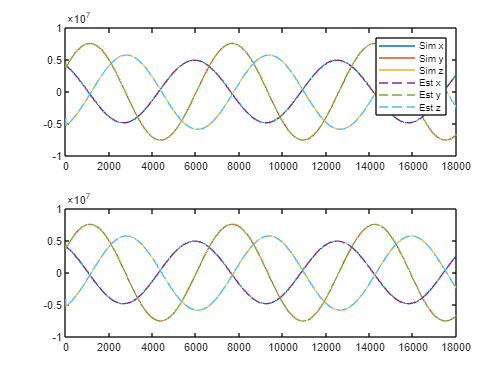

% Plot the error between estimated position and actual position for the GPS
% position and velocity based schemes

unpert_sim_sens_tout = unperturbed_sim_out.actual_pos.Time;
unpert_sim_pos = unperturbed_sim_out.actual_pos.Data;
est_pos_from_only_pos = unperturbed_sim_out.est_pos_meas_pos.Data;
est_pos_from_pos_and_vel = unperturbed_sim_out.est_pos_meas_pos_vel.Data;

figure;
tiledlayout(2, 1)
nexttile
plot(unpert_sim_sens_tout, unpert_sim_pos)
hold on
plot(unpert_sim_sens_tout, est_pos_from_only_pos, '--')
legend('Sim x', 'Sim y', 'Sim z', 'Est x', 'Est y', 'Est z')

nexttile
plot(unpert_sim_sens_tout, unpert_sim_pos)
hold on
plot(unpert_sim_sens_tout, est_pos_from_only_pos, '--')

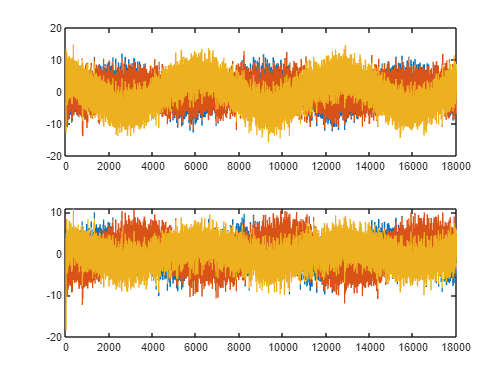


err_est_pos_from_only_pos = unpert_sim_pos - est_pos_from_only_pos;
err_est_pos_from_pos_and_vel = unpert_sim_pos - est_pos_from_pos_and_vel;

figure;
tiledlayout(2, 1);
nexttile
plot(unpert_sim_sens_tout(idx_start_ss:end), err_est_pos_from_only_pos(idx_start_ss:end, :));
nexttile
plot(unpert_sim_sens_tout(idx_start_ss:end), err_est_pos_from_pos_and_vel(idx_start_ss:end, :));

% Triggers the simulation of the EKF conc
perturbed_sim_out = sim("sim_perturbed_od_ekf", StopTime=num2str(sim_time));

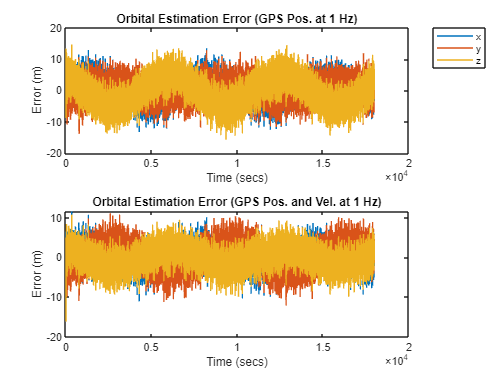



est_pos_from_only_pos = perturbed_sim_out.est_pos_meas_pos.Data;
est_pos_from_pos_and_vel = perturbed_sim_out.est_pos_meas_pos_vel.Data;

pert_sim_pos = perturbed_sim_out.actual_pos.Data;
err_est_pos_from_only_pos = pert_sim_pos - est_pos_from_only_pos;
err_est_pos_from_pos_and_vel = pert_sim_pos - est_pos_from_pos_and_vel;

figure;
tiledlayout(2, 1)
nexttile
grid on

plot(perturbed_sim_out.tout(idx_start_ss:end), err_est_pos_from_only_pos(idx_start_ss:end, :));
legend('x', 'y', 'z', 'Location', 'bestoutside')
title('Orbital Estimation Error (GPS Pos. at 1 Hz)')
xlabel('Time (secs)')
ylabel('Error (m)')

nexttile
grid on
plot(perturbed_sim_out.tout(idx_start_ss:end), err_est_pos_from_pos_and_vel(idx_start_ss:end, :));
title('Orbital Estimation Error (GPS Pos. and Vel. at 1 Hz)')
xlabel('Time (secs)')
ylabel('Error (m)')